# Short term trading strategy

Clear variables

clear;
clc;
tic

Load data

% m = matfile("pricevolumedata.mat","Writable",true) ;
loadDataInput

dataInput = struct with fields:
    closepriceTT: [1000×665 timetable]
     highpriceTT: [1000×665 timetable]
      indexclean: [2930×6 timetable]
      lowpriceTT: [1000×665 timetable]
     openpriceTT: [1000×665 timetable]
        volumeTT: [1000×665 timetable]


Test data and parameters

% Test objective and constraints function
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
paramsInput     = [70	106	5	3	8	14	107	29	4	4	6]

paramsInput =     70   106     5     3     8    14   107    29     4     4     6


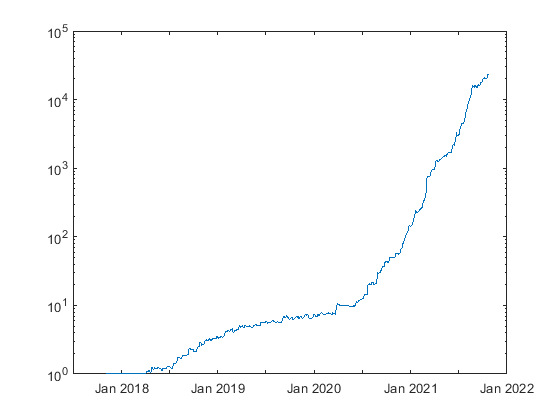

portEndValue = 2.2727e+04

portMinValue = 1

portMaxValue = 2.3267e+04

MaxDD = 0.1392

MaxDDIndex =    542
   553


drawdownDate = 2×1 datetime array
   2019-12-02
   2019-12-17


sharpeRatio = 4.8973

FortValueAtOptPoint = 2.0099e+04

PortRetOptPtEnd = 0.1308

optimPointDate = datetime
   2021-10-14


nYear = 3.9699

CAGR = 11.5142

dailyRetAvg = 0.0106

dailyRetMin = -0.1234

dailyRetMax = 0.3212

symRank = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'TCPI'}       {[1.5249]}    
    {'INAF'}       {[1.4762]}    
    {'FIRE'}       {[1.4442]}    
    {'BNBA'}       {[1.3930]}    
    {'BBHI'}       {[1.3901]}    
    {'KAEF'}       {[1.3480]}    
    {'ACST'}       {[1.3167]}    
    {'ABBA'}       {[1.3013]}    
    {'BOLA'}       {[1.2735]}    
    {'SURE'}       {[1.2349]}    
    {'FILM'}       {[1.2328]}    
    {'BBYB'}       {[1.2278]}    
    {'ZBRA'}       {[1.2217]}    
    {'MPPA'}       {[1.2209]}    
    {'FREN'}       {[1.2186]}    
    {'BABP'}       {[1.2092]}    


tradingSignalTT = tradingSignalFcnVectorized_v1 (paramsInput, dataInput) ;

% [portDailyRetTT, netDailyRetperSymTT] will be used further in the
% optimization section

[portDailyRetTT, netDailyRetperSymTT] = tradingBacktestFcn_v2 (tradingSignalTT, dataInput) ;

analyzeTradeResults


stockPick

stockPick = 6×2 table
     symbol     TradingSignal
    ________    _____________

    {'BBHI'}        {[1]}    
    {'MAPA'}        {[1]}    
    {'PANR'}        {[1]}    
    {'SGER'}        {[1]}    
    {'SRTG'}        {[1]}    
    {'SSMS'}        {[1]}    


Optimize parameters

startTime = uint64
2091313978561

optimPoint = 5

Objective or constraint function returned NaN.


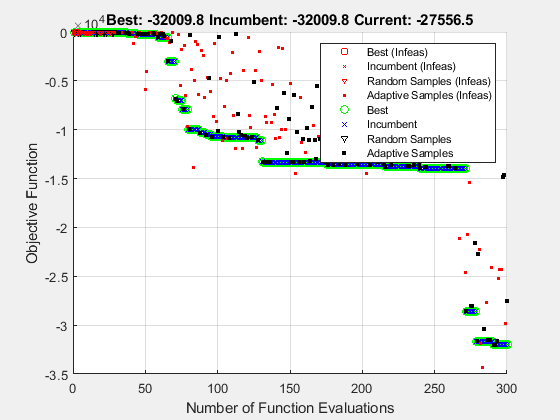

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     97    50     5     1    15     3   136    59     2     5     4


fval = -3.2010e+04

exitflag = 0

outpt = struct with fields:
        elapsedtime: 441.1176
          funccount: 300
    constrviolation: -0.0227
               ineq: [-0.0227 -4.5654]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 442.2634

optimParams_v4

Statistics and Analysis

Examine result of optimized params

paramsInput     = sol
tradingSignalTT = tradingSignalFcnVectorized_v1 (paramsInput, dataInput) ;
[portDailyRetTT, netDailyRetperSymTT] = tradingBacktestFcn_v2 (tradingSignalTT, dataInput) ;


Analyze results statistics

analyzeTradeResults 


Stock Picks

% Stock picks
stockpicks

Analyze the input parameters compared to its boundaries

% Examine result of optimized params
% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 

% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
counterhelp     = [1    2   3   4   5   6   7   8   9   10  11]
sol
lb              = [20   50  5   1   3   2   80  10  1   1   0] 
ub              = [150  150 60  6   20  30  250 60  10  8   15] 


End

toc